# Control por Realimentacion de estados.

clear; close all; clc;
sympref('FloatingPointOutput',true);
syms Mv L m R Iv Ib g       %%% Parametros
syms a b [4,1]              %%% Parametros Auxiliares
syms x x_dot_ f Xss [4,1]   %%% Estados, Campos Vectoriales 
syms u Uss U_dot_x U_x U_y U_dot_y                 %%% Entradas
syms r1                     %%% Referencia 
syms den(x1)

#### Parámetros.

%%%% Parametros
a=5/7; g=9.8; kbb=-a*g;
% r1=0.05; r2=0.1;

%%%% Variables Auxiliares
% kbb=5*g*r_arm/(7*L_beam);

#### Modelo del Sistema.

%%% Sistema NO Lineal
f(1) = x(2);
f(2) = a*(x(1)*U_dot_x^2+x(3)*U_dot_x*U_dot_y-g*sin(U_x));
f(3) = x(4);
f(4) = a*(x(3)*U_dot_y^2+x(1)*U_dot_x*U_dot_y-g*sin(U_y));
sys = (x_dot_ == f);

#### Sistema Linealizado.

%%% Matrices del sistema lineal en continuo
A1=[0 1;0 0];
B1=[0;-a*g];
C1=[1 0];
D1=0;

A2=[0 1;0 0];
B2=[0;-a*g];
C2=[1 0];
D2=0;       

Sys1c=ss(A1,B1,C1,D1);
Sys2c=ss(A2,B2,C2,D2);

%%% Sistema Ampliado
A1a = [A1 zeros(2,1); -C1 0];
B1a = [B1; 0];

A2a = [A2 zeros(2,1); -C2 0];
B2a = [B2; 0];

#### Diseño del controlador.

Polos:

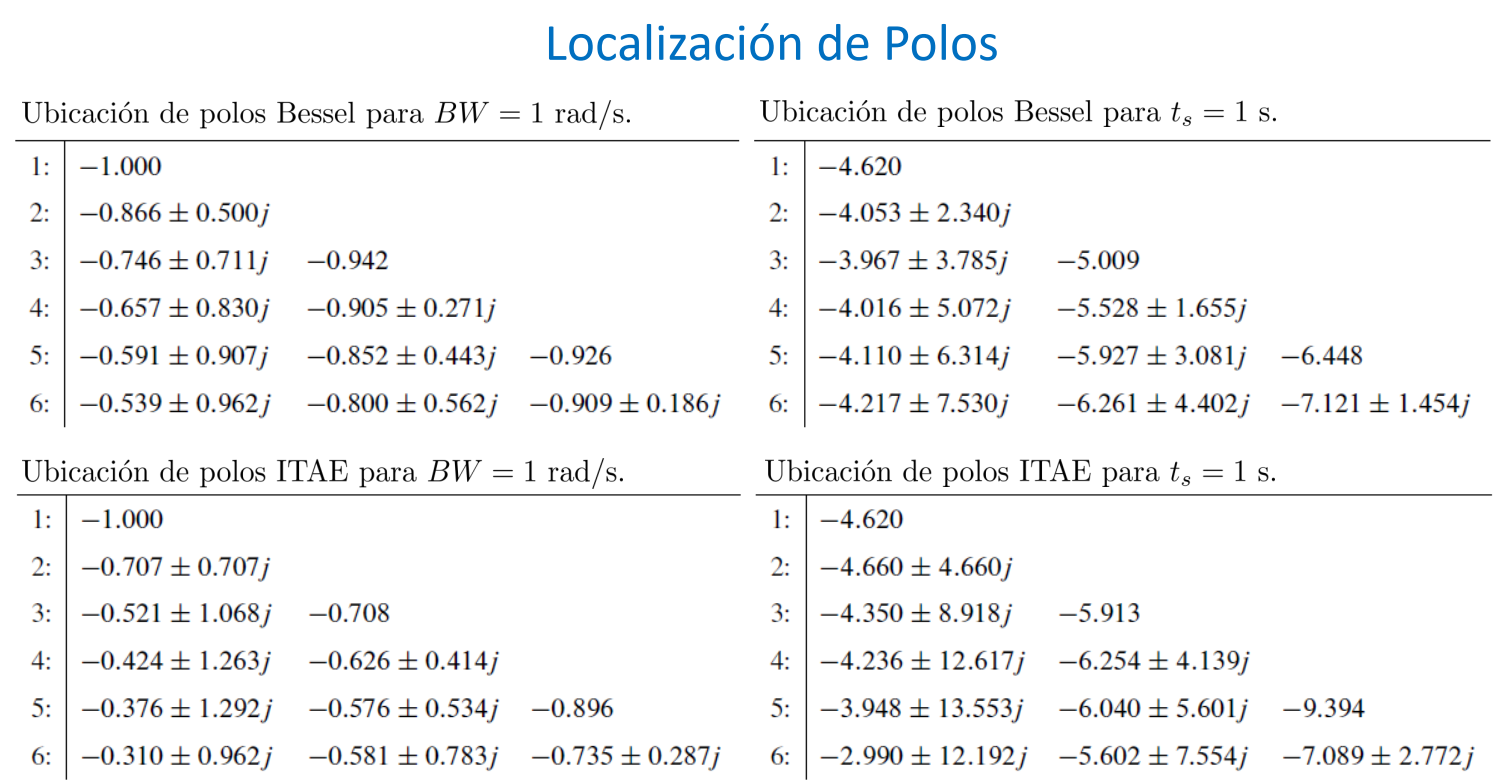

% Ubicacion de polos especificada
polos1 = [-0.5 -0.6 -0.7]*0.5;
polos2 = [-0.5 -0.6 -0.7]*0.5; %mas cerca del origen mas lento

%polos1 = [-3.967+3.785i -3.967-3.785i  -5.009]; % Bessel
%polos2 = [-3.967+3.785i -3.967-3.785i  -5.009]; % Bessel

K1a = place(A1a, B1a, polos1);
K2a = place(A2a, B2a, polos2);

%%% Calcular los polos del sistema con realimentación de estados
Sys1K = ss(A1a - B1a*K1a, B1a, [C1 0], D1);
Sys2K = ss(A2a - B2a*K2a, B2a, [C2 0], D2);

poles_Sys1K = pole(Sys1K);
poles_Sys2K = pole(Sys2K);

disp('Polos del sistema 1 con realimentación de estados:');

Polos del sistema 1 con realimentación de estados:


disp(poles_Sys1K);

   -0.3500
   -0.3000
   -0.2500




disp('Polos del sistema 2 con realimentación de estados:');

Polos del sistema 2 con realimentación de estados:


disp(poles_Sys2K);

   -0.3500
   -0.3000
   -0.2500



## Implementación de control con simulación ODE.

Condiciones iniciales y periodo de muestreo.

Tsim=120;            % Tiempo total de la simulación
Ts=0.15;            % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
x_01=[0 0 0 0]';    % Condiciones Inciales [pos, vel]
u1_ant=0; u2_ant=0; 
u1=0; u2=0;         % Señal de control para el primer instante de muestreo.
int_err1=0; int_err2=0;
x=zeros(Ns,4); usim=zeros(Ns,2); % Tamaño de vectores definido

ref1=0.1; ref2=0.1; %ref1=0.05; ref2=0.1;

e_ans1=0; e_ans2=0;

#### Ciclo de simulación.

for k=1:Ns
    du1=(u1-u1_ant); du2=(u2-u2_ant);
    u1_ant=u1;       u2_ant=u2;
    [~,xd]=ode23s('plantabp',Ts,x_01,[],u1,du1,u2,du2);   % Simular la planta para un Ts.
    xmed=xd(end,:)'; % Medir estados (la última señal se toma a los Ts segundos).
    %%% State Feedback Control
    e_act1=(ref1-xmed(1)); e_act2=(ref2-xmed(3));    % Cálculo del error
    int_err1=int_err1+((e_act1+e_ans1)*Ts)/2; 
    int_err2=int_err2+((e_act2+e_ans2)*Ts)/2;        % Integrador 
    u1=-(dot(K1a(1:2),xmed(1:2)))-K1a(end)*int_err1; % Señal de control
    u2=-(dot(K2a(1:2),xmed(3:4)))-K2a(end)*int_err2; % Señal de control

    %%% Actualiza Variables y guarda para graficar
    e_ans1=e_act1; e_ans2=e_act2;
    
    x_01=xmed; x(k,:)=xmed'; usim(k,:)=[u1 u2]; 
    %Referencia Fija:
    %ref1=-ref1; ref2;
  
    %% Cambia Referencias
    if k==round(Ns/5)
        ref1=-ref1; ref2;
    end
    if k==round(2*Ns/5)
        ref1; ref2=-ref2;
    end
    if k==round(3*Ns/5)
        ref1=-ref1; ref2;
    end
    if k==round(4*Ns/5)
        ref1; ref2=-ref2;
    end
  
    
end

#### Graficación.

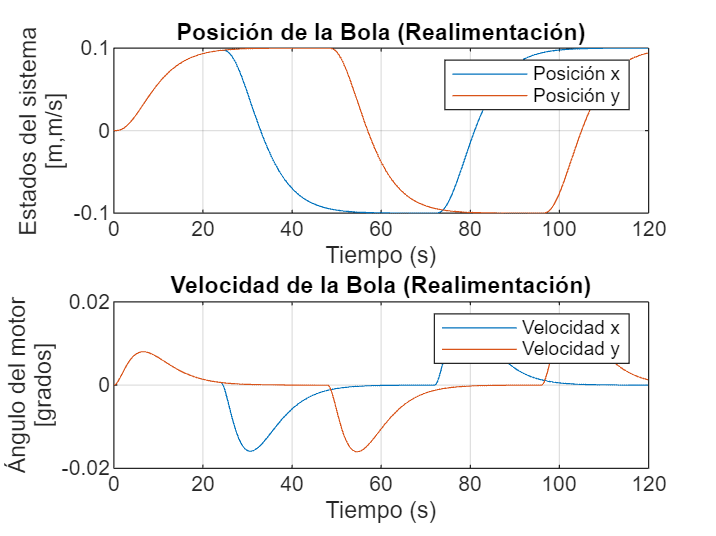

tdisc=0:Ts:Ns*Ts-Ts;
figure; subplot(2,1,1); plot(tdisc,[x(:,1) x(:,3)]); title('Posición de la Bola (Realimentación)');
xlabel('Tiempo (s)'); ylabel({'Estados del sistema','[m,m/s]'});
legend('Posición x','Posición y');
grid on;

subplot(2,1,2); plot(tdisc,[x(:,2) x(:,4)]); title('Velocidad de la Bola (Realimentación)');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
legend('Velocidad x','Velocidad y');
grid on;

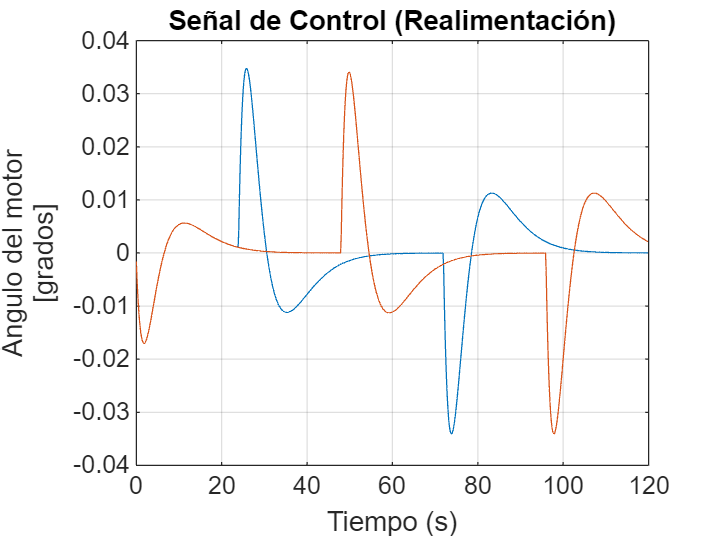


figure
plot(tdisc,usim*180/pi); title('Señal de Control (Realimentación)');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
grid on;

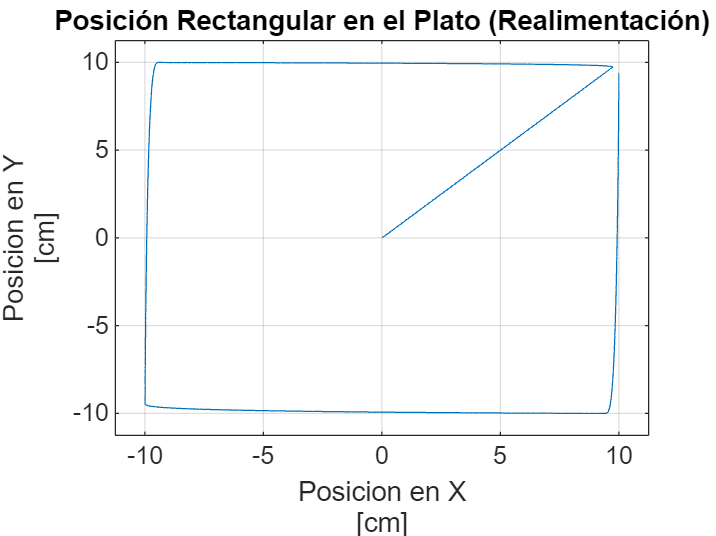


figure;
plot(x(:,1)*100,x(:,3)*100);title('Posición Rectangular en el Plato (Realimentación)');
xlabel({'Posicion en X','[cm]'}); ylabel({'Posicion en Y','[cm]'});
xlim([-22.5/2 22.5/2]); ylim([-22.5/2 22.5/2]); 
grid on;


%%% Indices de desempeño (ITAE)
t = tdisc;
r = ref1(1)*ones(size(t));
% y = -1*(x(:,1)'-x(1,1));        % ref<x_0
y = x(:,1)';                      % ref>x_0

% ise = sum((r-y).^2)*Ts;         % ISE
% itse = sum(t.*(r-y).^2)*Ts;     % ITSE
% iae = sum(abs(r - y))*Ts;       % IAE
%itae = sum(t.*abs(r - y))*Ts;   % ITAE

If = stepinfo(y,t);               % Tes,Ovs

fprintf('\n\n\n Indices de Desempeño.\n');




 Indices de Desempeño.


% fprintf('   ISE: %f \n',ise);
% fprintf('   ITSE: %f \n',itse);
% fprintf('   IAE: %f \n',iae);
%fprintf('   ITAE: %f \n',itae);
fprintf(' Tiempo de Establecimiento: %f segundos \n',If.SettlingTime);

 Tiempo de Establecimiento: 100.753405 segundos 


fprintf(' Sobre Paso: %f%% \n\n',If.Overshoot);

 Sobre Paso: 0.000000% 




x_mat= x; u_mat=usim;

# Control Referencia Simple.

## Implementación de control con simulación ODE.

Condiciones iniciales y periodo de muestreo.

Tsim=60;            % Tiempo total de la simulación
Ts=0.15;            % Periodo de muestreo
Ns=round(Tsim/Ts);  % Número de periodos de muestreo que tendrá la simulación.
x_01=[0 0 0 0]';    % Condiciones Inciales [pos, vel]
u1_ant=0; u2_ant=0; 
u1=0; u2=0;         % Señal de control para el primer instante de muestreo.
int_err1=0; int_err2=0;
x=zeros(Ns,4); usim=zeros(Ns,2); % Tamaño de vectores definido

ref1=0.1; ref2=0.1; %ref1=0.05; ref2=0.1;

e_ans1=0; e_ans2=0;

#### Ciclo de simulación.

for k=1:Ns
    du1=(u1-u1_ant); du2=(u2-u2_ant);
    u1_ant=u1;       u2_ant=u2;
    [~,xd]=ode23s('plantabp',Ts,x_01,[],u1,du1,u2,du2);   % Simular la planta para un Ts.
    xmed=xd(end,:)'; % Medir estados (la última señal se toma a los Ts segundos).
    %%% State Feedback Control
    e_act1=(ref1-xmed(1)); e_act2=(ref2-xmed(3));    % Cálculo del error
    int_err1=int_err1+((e_act1+e_ans1)*Ts)/2; 
    int_err2=int_err2+((e_act2+e_ans2)*Ts)/2;        % Integrador 
    u1=-(dot(K1a(1:2),xmed(1:2)))-K1a(end)*int_err1; % Señal de control
    u2=-(dot(K2a(1:2),xmed(3:4)))-K2a(end)*int_err2; % Señal de control

    %%% Actualiza Variables y guarda para graficar
    e_ans1=e_act1; e_ans2=e_act2;
    
    x_01=xmed; x(k,:)=xmed'; usim(k,:)=[u1 u2]; 
    %Referencia Fija:
    %ref1=-ref1; ref2;
  %{
    %% Cambia Referencias
    if k==round(Ns/5)
        ref1=-ref1; ref2;
    end
    if k==round(2*Ns/5)
        ref1; ref2=-ref2;
    end
    if k==round(3*Ns/5)
        ref1=-ref1; ref2;
    end
    if k==round(4*Ns/5)
        ref1; ref2=-ref2;
    end
  %}
    
end

#### Graficación.

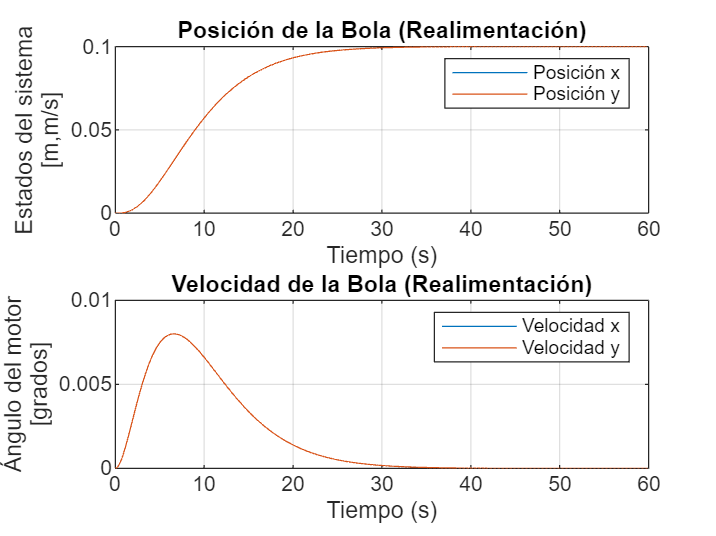

tdisc=0:Ts:Ns*Ts-Ts;
figure; subplot(2,1,1); plot(tdisc,[x(:,1) x(:,3)]); title('Posición de la Bola (Realimentación)');
xlabel('Tiempo (s)'); ylabel({'Estados del sistema','[m,m/s]'});
legend('Posición x','Posición y');
grid on;
subplot(2,1,2); plot(tdisc,[x(:,2) x(:,4)]); title('Velocidad de la Bola (Realimentación)');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
legend('Velocidad x','Velocidad y');
grid on;

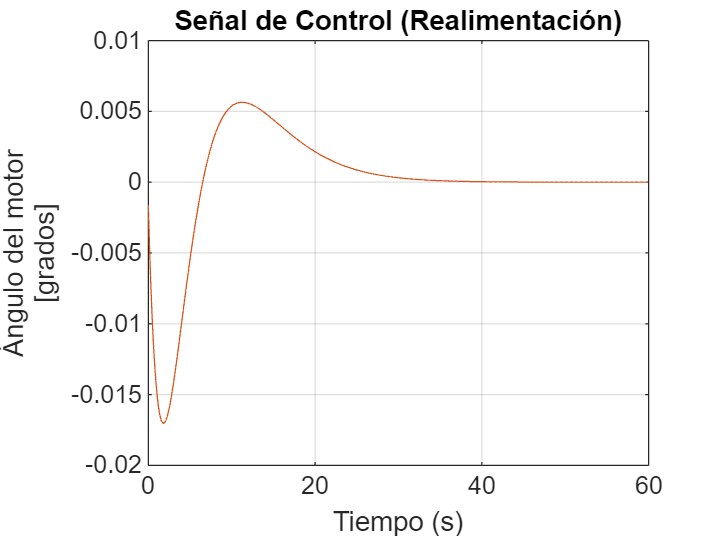


figure
plot(tdisc,usim*180/pi); title('Señal de Control (Realimentación)');
xlabel('Tiempo (s)'); ylabel({'Ángulo del motor','[grados]'});
grid on;

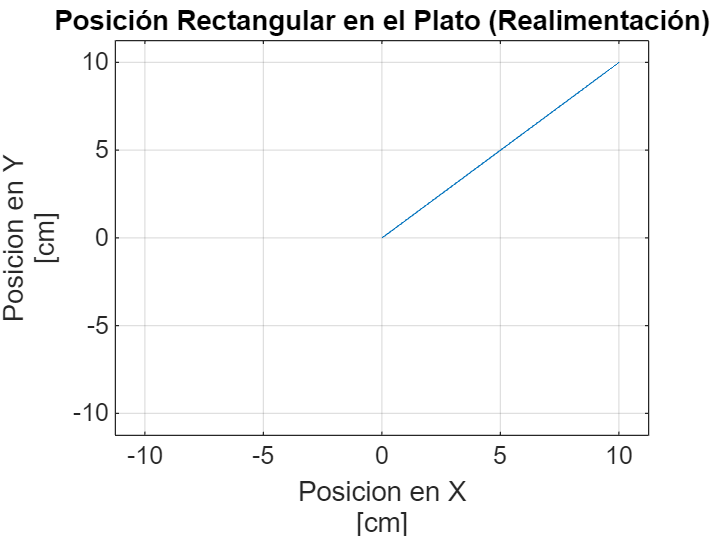


figure;
plot(x(:,1)*100,x(:,3)*100);title('Posición Rectangular en el Plato (Realimentación)');
xlabel({'Posicion en X','[cm]'}); ylabel({'Posicion en Y','[cm]'});
xlim([-22.5/2 22.5/2]); ylim([-22.5/2 22.5/2]); 
grid on;


%%% Indices de desempeño (ITAE)
t = tdisc;
r = ref1(1)*ones(size(t));
% y = -1*(x(:,1)'-x(1,1));        % ref<x_0
y = x(:,1)';                      % ref>x_0

% ise = sum((r-y).^2)*Ts;         % ISE
% itse = sum(t.*(r-y).^2)*Ts;     % ITSE
% iae = sum(abs(r - y))*Ts;       % IAE
 itae = sum(t.*abs(r - y))*Ts;   % ITAE

If = stepinfo(y,t);               % Tes,Ovs

fprintf('\n\n\n Indices de Desempeño (Realimentación). \n');




 Indices de Desempeño (Realimentación). 


% fprintf('   ISE: %f \n',ise);
% fprintf('   ITSE: %f \n',itse);
% fprintf('   IAE: %f \n',iae);
fprintf('   ITAE: %f \n',itae);

   ITAE: 6.879504 


fprintf(' Tiempo de Establecimiento: %f segundos \n',If.SettlingTime);

 Tiempo de Establecimiento: 25.703000 segundos 


fprintf(' Sobre Paso: %f%% \n\n',If.Overshoot);

 Sobre Paso: 0.000000% 




x_mat= x; u_mat=usim;
